modulePath = 'C:\Users\Asus\Studia\Indywidualny Program Studiów\IPS - Projekt\dane - semestr 5\MATLAB_project\python_modules';
insert(py.sys.path, int32(0), modulePath);
load('C:\Users\Asus\Studia\Indywidualny Program Studiów\IPS - Projekt\dane - semestr 5\MATLAB_project\ab_diff_zestaw.mat')

function results_py = model_hybrid(y_train, y_test, step_length,  ma_window, season_period)
    py_model = py.importlib.import_module("model_hybrid");
    results_py = py_model.model_hybrid(...
        y_train, ... 
        y_test, ...
        step_length, ...
        pyargs('ma_window', ma_window, 'season_period', season_period, 'verbose', true) ...
    ).double';
end

% Wzór R2_1 (Standardowy Współczynnik Determinacji)
R2_classic = @(y_true, y_pred) 1 - (sum((y_true(:) - y_pred(:)).^2) / sum((y_true(:) - mean(y_true(:))).^2));

% Wzór R2_2 (Frakcja Wyjaśnionej Wariancji)
R2_alt = @(y_true, y_pred) sum((y_pred(:) - mean(y_true(:))).^2) / sum((y_true(:) - mean(y_true(:))).^2);

train_data = ab_diff_train_norm;
test_data = ab_diff_test_norm;

dlugosc_testu_oryginalna = 2880; % Horyzont w oryginalnej dziedzinie czasu (2880 próbek)

test_length = dlugosc_testu_oryginalna;
step_length = 96;

% Przewidywania A1 - model hybrydowy
prediction = model_hybrid(train_data, test_data(1:test_length), step_length, 32, 96*7);

Step: 1 / 30
Step: 2 / 30
Step: 3 / 30
Step: 4 / 30
Step: 5 / 30
Step: 6 / 30
Step: 7 / 30
Step: 8 / 30
Step: 9 / 30
Step: 10 / 30
Step: 11 / 30
Step: 12 / 30
Step: 13 / 30
Step: 14 / 30
Step: 15 / 30
Step: 16 / 30
Step: 17 / 30
Step: 18 / 30
Step: 19 / 30
Step: 20 / 30
Step: 21 / 30
Step: 22 / 30
Step: 23 / 30
Step: 24 / 30
Step: 25 / 30
Step: 26 / 30
Step: 27 / 30
Step: 28 / 30
Step: 29 / 30
Step: 30 / 30
Koniec predykcji.


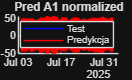

% Narysuj wykres
figure;
hold on;
plot(ab_diff_test.Time(1:test_length), test_data(1:test_length), 'Color','blue', 'DisplayName','Test');
plot(ab_diff_test.Time(1:test_length), prediction, 'Color','red','DisplayName','Predykcja');
title('Pred A1 normalized');
legend;

y_test = test_data(1:length(prediction))';

mae_score = mae(y_test, prediction)

mae_score = 45.0520

mape_score = mape(y_test, prediction)

mape_score = 100.3146

rmse_score = rmse(y_test, prediction)

rmse_score = 45.9308

r2_classic = R2_classic(y_test, prediction)

r2_classic = -1.7601e+04

r2_alt = R2_alt(y_test, prediction)

r2_alt = 1.7607e+04

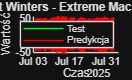


figure;
hold on;
%plot(ab_diff_train.Time, ab_diff_train_norm, 'Color','blue','DisplayName','Trening');
plot(ab_diff_test.Time(1:length(prediction)), ab_diff_test_norm(1:length(prediction)), 'Color','green','DisplayName','Test');
plot(ab_diff_test.Time(1:length(prediction)), prediction, 'Color','red','DisplayName','Predykcja');
xlabel('Czas');
ylabel('Wartość');
title("Predykcja Holt Winters - Extreme Maching Learning: A1")
legend;

% Tworzenie tabeli z czasem, danymi i predykcją
T_z_czasem = table(ab_diff_test.Time(1:dlugosc_testu_oryginalna), ...
                   ab_diff_test_norm(1:dlugosc_testu_oryginalna), ...
                   prediction(1:dlugosc_testu_oryginalna)', ...
    'VariableNames', {'Czas', 'Dane_Prawdziwe', 'Predykcja'}');

writetable(T_z_czasem, "pred_ab_HYBRYDA_" + num2str(step_length) + "_month.xlsx");